# Visión por Computador - Sesión 3

    Ferran Velasco Olivera

    Joaquín Gómez Sánchez

## Coding Dilatación

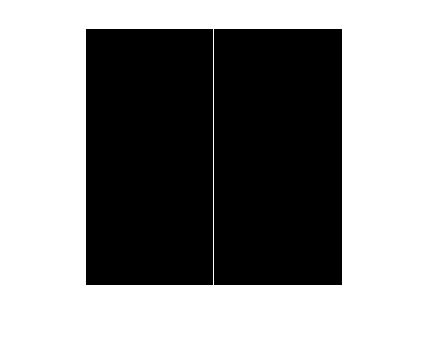

im = false(256);
im(:, 128) = 1;

imshow(im)


ee = [1 1 1]

ee =      1     1     1


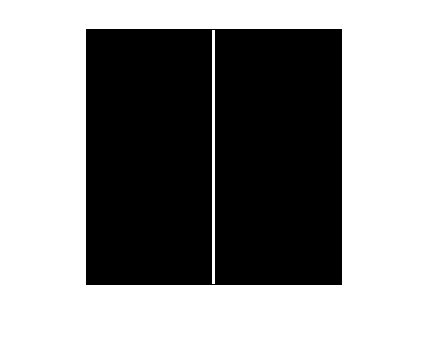

imDil1 = false(256);
for i = 2:255
    for j = 2:255
        if (im(i, j) == 1)
            imDil1(i, j-1:j+1) = imDil1(i, j-1:j+1) | ee;
        end
    end
end

imshow(imDil1)

Función de dilatación:

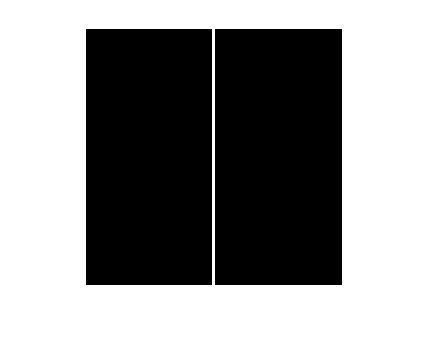

imDil2 = imdilate(im, ee);
figure, imshow(imDil2)

## Dilatación, Erosión, Open y Close

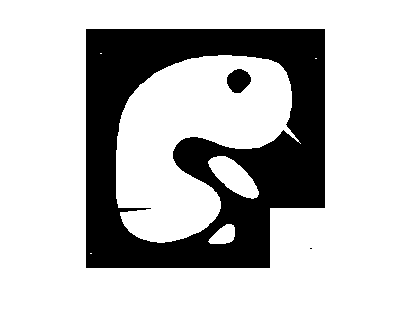

im2 = imread('blob.tif');
figure, imshow(im2)


ee2 = strel('disk', 5);

Dilatación:

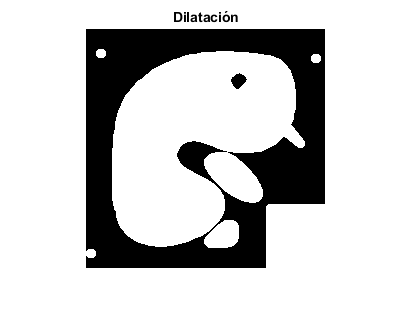

imDil3 = imdilate(im2, ee2);
figure, imshow(imDil3), title('Dilatación')

Erosión:

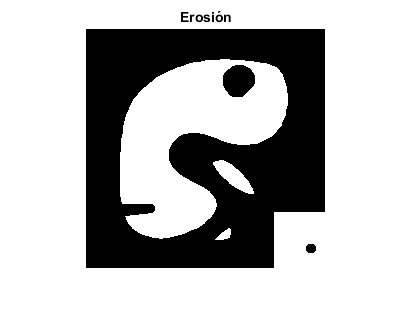

imEro1 = imerode(im2, ee2);
figure, imshow(ero), title('Erosión')

Open y close:

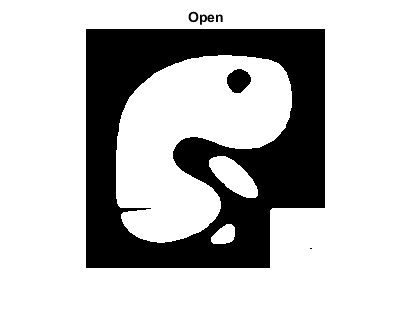

op = imopen(im2, ee2);
cl = imclose(im2, ee2);
figure, imshow(op), title('Open')

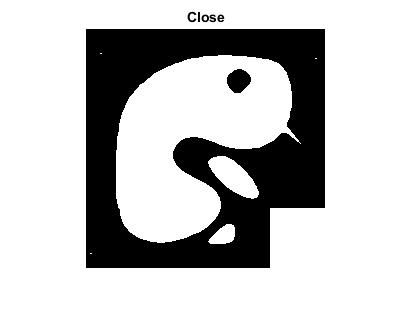

figure, imshow(cl), title('Close')

## Dilatación condicional

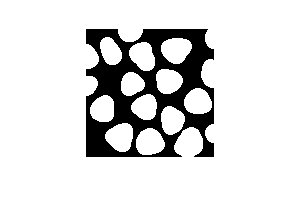

im3 = imread('blob3.tif');
imshow(im3)

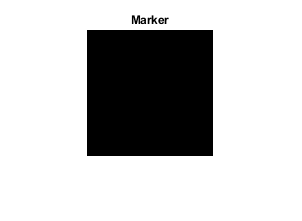


mark = true(128);
mark(2:end-1, 2:end-1) = 0;
figure, imshow(mark), title('Marker')

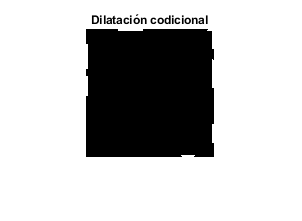


ee3 = strel('disk',1);

imDil4 = imdilate(mark, ee3) & im3;
figure, imshow(imDil4), title('Dilatación codicional')

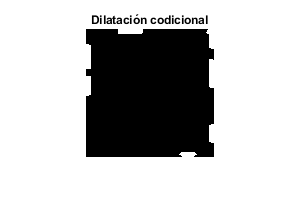


imDil4 = imdilate(imDil4, ee3) & im3;
imDil4 = imdilate(imDil4, ee3) & im3;
imDil4 = imdilate(imDil4, ee3) & im3;

figure, imshow(imDil4), title('Dilatación codicional')

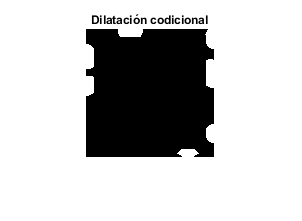


imDil4 = imdilate(imDil4, ee3) & im3;
imDil4 = imdilate(imDil4, ee3) & im3;
imDil4 = imdilate(imDil4, ee3) & im3;

figure, imshow(imDil4), title('Dilatación codicional')

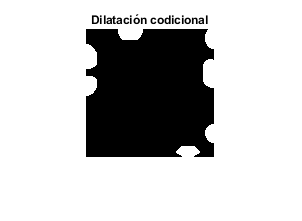


imDil4 = imdilate(imDil4, ee3) & im3;
imDil4 = imdilate(imDil4, ee3) & im3;
imDil4 = imdilate(imDil4, ee3) & im3;

figure, imshow(imDil4), title('Dilatación codicional')

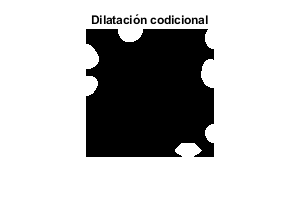


imDil4 = imdilate(imDil4, ee3) & im3;
imDil4 = imdilate(imDil4, ee3) & im3;
imDil4 = imdilate(imDil4, ee3) & im3;

figure, imshow(imDil4), title('Dilatación codicional')

Eliminación de celulas en bordes:

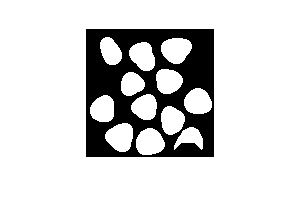

imRes = im3 - imDil4;
imshow(imRes)

Reconstrucción:

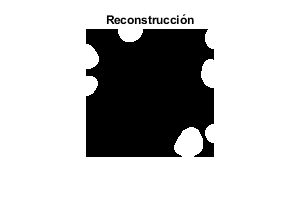

imRec = imreconstruct(mark, im3);
figure, imshow(imRec), title('Reconstrucción')

## Tapando agujeros

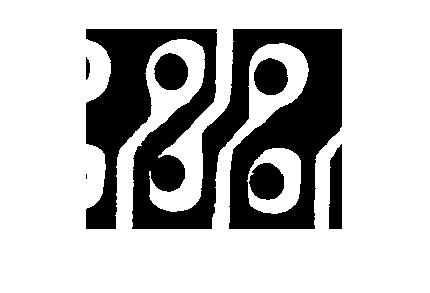

im4 = imread('pcbholes.tif');
imshow(im4)

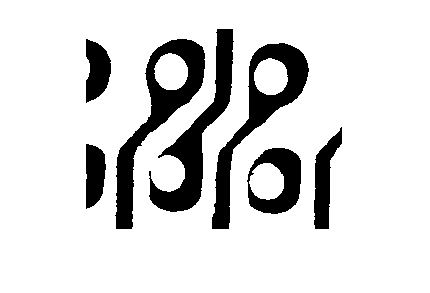

notIm4 = logical(true(size(im4)) - im4);
imshow(notIm4)

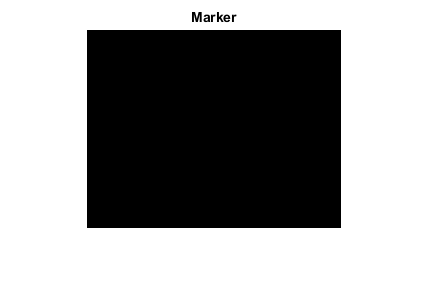


mark2 = true(size(notIm4));
mark2(2:end-1, 2:end-1) = 0;
figure, imshow(mark2), title('Marker')

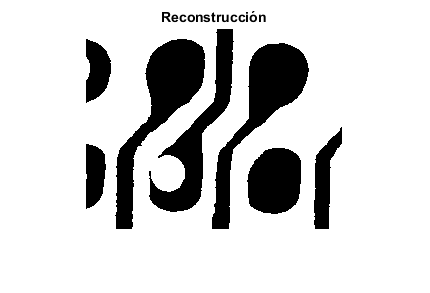


imRec2 = imreconstruct(mark2, notIm4);
figure, imshow(imRec2), title('Reconstrucción')

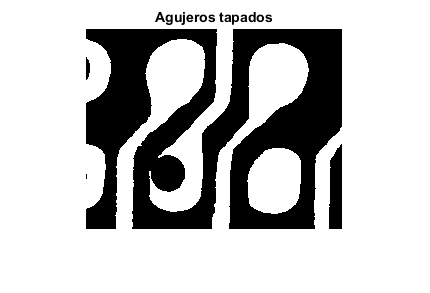


imRes2 = logical(true(size(imRec2)) - imRec2);
figure, imshow(imRes2), title('Agujeros tapados')

## Figuras

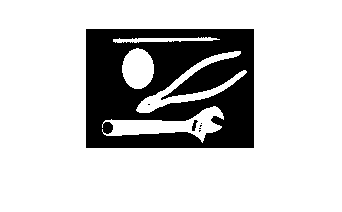

im5 = imread('tools.tif');
figure, imshow(im5);

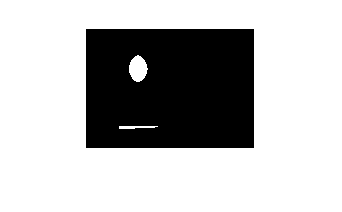


ee4 = strel('disk', 7);
ero2 = imerode(im5, ee4);
figure, imshow(ero2);

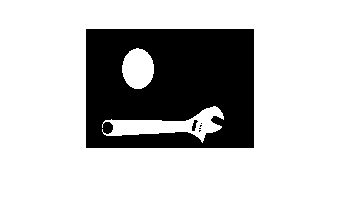


imRec3 = imreconstruct(ero2, im5);
figure, imshow(imRec3);

## Letters

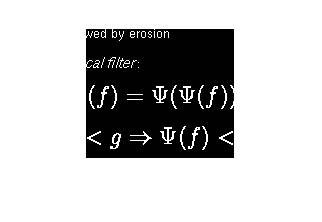

im6 = imread('letters.tif');
figure, imshow(im6)

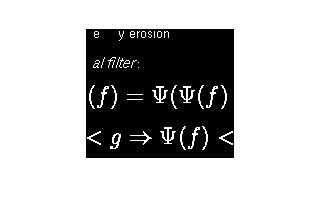


mark3 = true(size(im6));
mark3(2:end-1, 2:end-1) = 0;
im6 = im6 - imreconstruct(mark3, im6);
figure, imshow(im6)

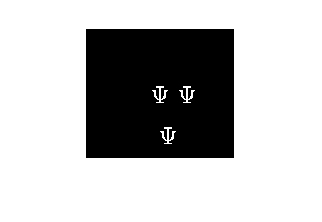


ee5 = strel('line', 15, 90);
ero3 = imerode(im6, ee5);

imRec4 = imreconstruct(ero3, im6);
figure, imshow(imRec4);